load CosineKNNModelKernel16.mat

webcamlist;
cam = webcam(1);

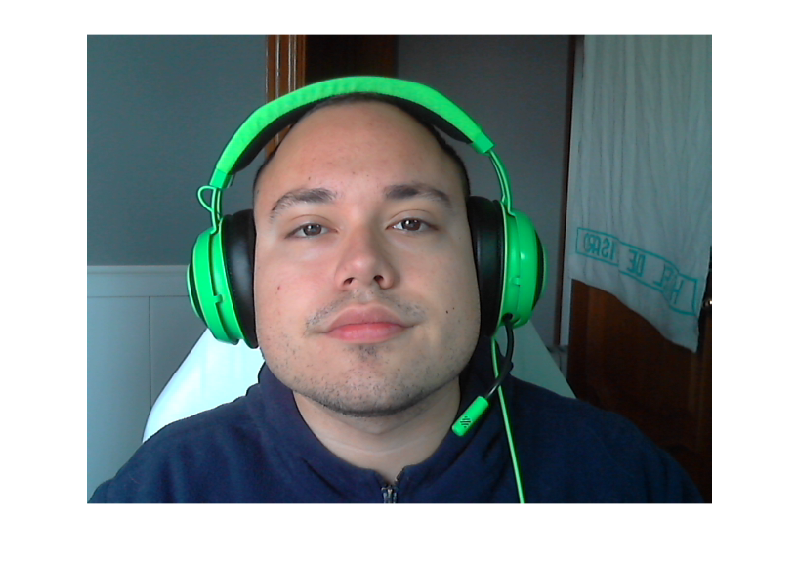

imagenOriginal = snapshot(cam);
imshow(imagenOriginal)

imagen = imresize(imagen, 2);

imagen = 960×1280×3 uint8 array
imagen(:,:,1) =

    99    99    97    97    97    97    96    96    94    94    94    93    92    91    91    92    93    94    94    95    98    99    98    98    97    97    97    96    94    93    93    93    93    93    93    94    95    96    96    97   100   101   101   101    99    99    99    98    94    93    93    93    91    91    91    91    89    89    89    89    89    89    88    89    90    91    91    92    93    94    94    94    93    93    93    94    96    97    96    97    98    99    99    98    96    96    98    97    92    91    91    90    89    88    89    89    89    89    89    90    92    93    93    93    95    95    95    95    96    96    96    95    94    92    92    90    89    88    88    88    88    88    88    88    90    90    90    92    95    96    97    98   100   101   101   101    99    99    99    99    98    98    99    99    98    98    98    97    96    95    96    96    96    96    96    96    96    96   

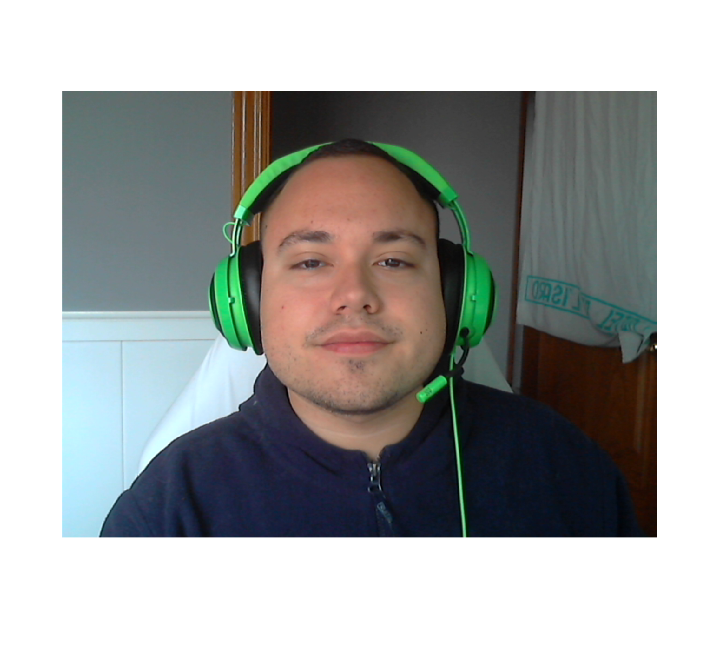

imshow(imagen) 

alturaImagen = height(imagen)

alturaImagen = 960

anchuraImagen = width(imagen)

anchuraImagen = 1280

tamanoVentanaAncho = 513;
tamanoVentanaAlto = 113;

moverAlto = fix(tamanoVentanaAlto / 2)

moverAlto = 56

moverAncho = fix(tamanoVentanaAncho / 2)

moverAncho = 256

prediccion = single
0

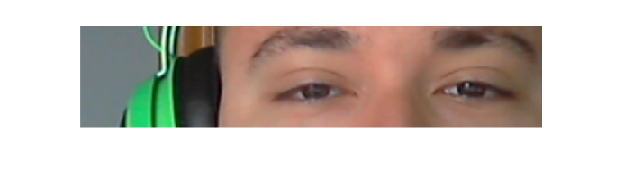

for i = 300:moverAlto:alturaImagen-moverAlto
    for j = 277:moverAncho:anchuraImagen-moverAncho

        indicei = i;
        indicej = j;

        if (indicei+tamanoVentanaAlto > alturaImagen)
            indicei = alturaImagen - tamanoVentanaAlto;
        end
            
        if (indicej+tamanoVentanaAncho > anchuraImagen)
            indicej = anchuraImagen - tamanoVentanaAncho;
        end

        muestra = imagen(indicei:indicei+tamanoVentanaAlto-1, indicej:indicej+tamanoVentanaAncho-1, :);
        prediccion = ejecutarPredictor(muestra, CosineKNNModelKernel16)
        
        imshow(muestra)
        
    end
end